# Run the Simulation programatically:

## Overview:

As an alternative to opening the Simulink model and clicking on the RUN button, we can alos run a Simulink model programatically. Why ? - this is especially useful when:

- you want to do a parameter sweep, eg: run 1000's of simulations and varying parameters for each run

- you want to solve an optimization problem and teh Simulink model can be part of the "Cost Function"

## Good Resources:

- ` web(fullfile(docroot, 'simulink/examples/multiple-simulations-workflow-tips.html'))`

- ` web(fullfile(docroot, 'simulink/ug/optimize-estimate-and-sweep-block-parameter-values.html'))`

## Configure the model - part 1:

Although we could use the **BASE workspace** for storing our model variables/parameters ...  a "good practice" is to NOT use it when you're running the model programatically - especially when you start doing multiple runs of your model (eg: parameter sweeps).

So? - So we'll configure the model to use the **MODEL workspace** rather than the common BASE workspace.

THE_MODEL = 'bh_lactose_model';
open_system(THE_MODEL);
hws = get_param(THE_MODEL,'modelworkspace');
hws.DataSource = 'MATLAB Code'

hws = Simulink.ModelWorkspace
    DataSource: 'MATLAB Code'
    MATLABCode: ''


hws.MATLABCode = 'bh_lactose_to_lactic_params';

% now force the MATLAB code to run and to populate the MODEL's workspace
hws.reload

ode_params_table = 11×3 table
                   Value      Units            Description       
                  ________    ______    _________________________

    K_is               100    'g/L'     ''                       
    K_sp               205    'g/L'     'initial stable time'    
    P_ix              2.39    'TBC'     'end ph'                 
    P_mx              25.9    'TBC'     'end ph'                 
    alpha               15    'TBC'     'decrease rate'          
    mu_max           0.909    '1/hr'    ''                       
    q_pmax            0.05    'TBC'     'decrease rate sig'      
    q_smax          180.42    'TBC'     ''                       
    in_lactate           0    'g/L'     'initial lacta

## Configure the model - part 2:

Specify some model parameters.  In particular I want to save the ROOT level output (ie the ORANGE block) to a variable called "*brads_yout*".

simIn= Simulink.SimulationInput(THE_MODEL);

% next configure the Model parameters
simIn = simIn.setModelParameter('SaveOutput',     'on');
simIn = simIn.setModelParameter('OutputSaveName', 'brads_yout');
simIn = simIn.setModelParameter('SaveFormat',     'Dataset');
simIn = simIn.setModelParameter('StopTime',       '10');

## So now RUN your model

simOut = sim( simIn )

Evaluating callback 'MaskDialog' for bh_lactose_model/Compare To Constant
Callback: sl('zeroCrossEnable', gcbh);


simOut =   Simulink.SimulationOutput:

             brads_yout: [1x1 Simulink.SimulationData.Dataset] 
                logsout: [1x1 Simulink.SimulationData.Dataset] 
                   tout: [25x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


## Close the model - do NOT save any changes

tf_save_stuff = false;
close_system(THE_MODEL, tf_save_stuff)

## Get the logged data and do some post Processing

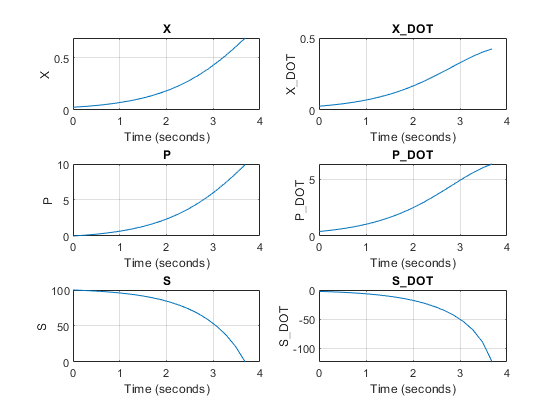

X = simOut.brads_yout{1}.Values.X;
P = simOut.brads_yout{1}.Values.P;
S = simOut.brads_yout{1}.Values.S;

X_DOT = simOut.brads_yout{1}.Values.X_DOT;
P_DOT = simOut.brads_yout{1}.Values.P_DOT;
S_DOT = simOut.brads_yout{1}.Values.S_DOT;

% do some plots
LOC_do_plots([X,P,S], [X_DOT, P_DOT, S_DOT])

## **Local functions**

function LOC_do_plots(XPS, XPS_DOT)
    
    h(1) = subplot(3,2,1); plot(XPS(1));      title('X')
    h(2) = subplot(3,2,2); plot(XPS_DOT(1));  title('X_DOT', 'Interpreter', 'none');
    h(3) = subplot(3,2,3); plot(XPS(2));      title('P')
    h(4) = subplot(3,2,4); plot(XPS_DOT(2));  title('P_DOT', 'Interpreter', 'none');
    h(5) = subplot(3,2,5); plot(XPS(3));      title('S')
    h(6) = subplot(3,2,6); plot(XPS_DOT(3));  title('S_DOT', 'Interpreter', 'none');
    
    % put a grid on every axes
    arrayfun( @(x) grid(x,'on'), h) 
    
    % Fix up the tex interpreted UNDERSCORES
    for kk=1:length(h)
        tmp = findall(h(kk), 'Type', 'Text');
        if(~isempty(tmp))
            set(tmp,'Interpreter', 'none')
        end    
    end
        
end % LOC_do_plots()